# Test Transform Points Function

Objective: The code below will test your *transform_points *function. It outputs a plot that will show the data point in the robot frame and the global frame. 

Helper Functions: Below are the helper functions used in this exercise:

- plot_frames*: *plots a data point both in the robot frame and the global frame.The robot is a black circle with a radius pointing in its positive x direction, and the data point is represented by a small red circle.

**EXERCISE:**

You can use the code below to test your function. Feel free to change the values of the variables *robot_pose* and *dataxy_robot *and examine the resulting plots. You can also add multiple data points at once (each column of the variable *dataxy_robot* represents a new point).

Complete the code below to:

- Define two inputs. Define the robot post (x,y, theta) in the global frame and the data point (x, y) relative to the robot pose 

- Transform the data point to the global frame

**COMPLETE THE CODE BELOW**

% 1. Define inputs
robot_pose = [-1; 1; pi/4]; % position of the robot in global frame
dataxy_robot = [1; 2]; % data point in robot frame

% 2. Transform the data point to the global frame using the
% transform_points function
dataxy_global= transform_points(robot_pose, dataxy_robot); % YOUR CODE HERE


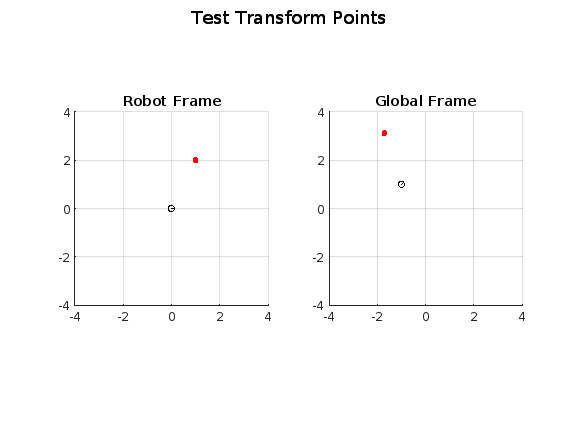

%Plot
plot_frames(robot_pose, dataxy_robot, dataxy_global, "Test Transform Points"); 

Expected Results: If you've implemented the *transform_points* function correctly, the data point (red dot) will be in the same location relative to the robot pose and heading.  However these plots will look different because of the different reference frames. Remember that in the robot frame, the robot's position is always [0; 0; 0]. 

Debugging Tips: If you are having trouble completing your *transform_points* function, below are some tips:

- First, test the rotation matrix aspect of the code only. Set the robot pose to [0,0] and the non-zero heading of your choosing. Run this *test_transform_points* script to test. Do the robot and data point rotate the heading amount in the global reference frame?

- Next, test the translation. Set the robot pose to a non-zero x-y position with a 0 heading. Run this *test_transform_points* script to test. Do the robot and data point move to the robot pose in the global reference frame?

Check Your Comprehension:  Do your results match? Are these the results you expected? 

- Try changing the robot pose and the data point inputs to further test your function. 

Add multiple data points at once to transform and plot.